Rm = 1.6;      % Armature Resistance(Ohm)
Lm = 0.001;    % Inductance(Henry)
K = 0.00636;  % Motor constant( V/rad)
Bm = 2.7e-6;   % Viscous friction of the motor at no load)
N = 52.1;          % gear ratio(as present in the documentation of the motor)

% Physical parameters
m_wheel = 0.5;              % kg (wheel only)
m_robot_total = 20;        % kg ← need this number
r_wheel = 0.0625;           % m

% Inertia calculations
J_wheel_rot = 0.5 * m_wheel * r_wheel^2;           % wheel spinning = 0.000976 ✅
J_robot_lin = (m_robot_total/4) * r_wheel^2;       % body moving linearly
J_rotor = 0.0000025;                               % rotor

% Reflect everything to motor shaft
J_reflected_wheel = J_wheel_rot / N^2;
J_reflected_robot = J_robot_lin / N^2;

% Total
Jm = J_rotor + J_reflected_wheel + J_reflected_robot; 
% Simulation parameters
sim_stop_time = 15 % simulation time in seconds

sim_stop_time = 15

sim_step_time = 0.001 % how often we will log the details

sim_step_time = 1.0000e-03

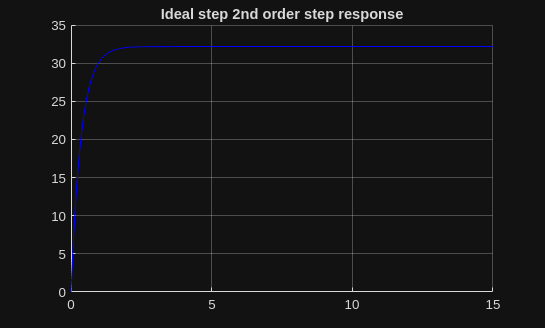



% plotting the step reference
vref = 11.8; % reference voltage to see the motor 

% putting in the LGain for the feedback loop
LGain = 1/N; 

% RUnning the simulink diagram
sim('Meccanum_drive.slx');

figure(1);


hold on;
h_step = plot(tsim, (theta_dot/N), 'b');
xlabel = ('time_step');
y_label = ('speed rad/sec');
title('Ideal step 2nd order step response');
grid on;

## Ideal PI controller for the motor

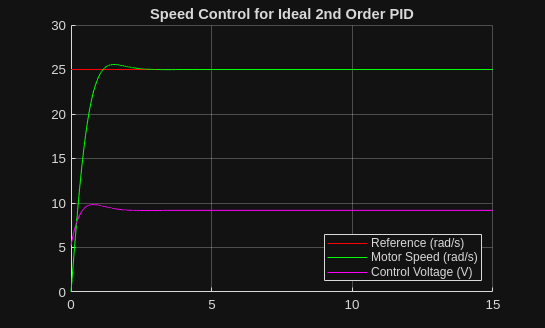

% Reset figures and simulation state
figure(3); clf; hold on;

% Reset sim initial conditions
set_param('PID_ideal_1', 'LoadInitialState', 'off');
set_param('PID_ideal_1', 'SaveFinalState', 'off');

% Gains
ref_speed = 25;
kp = 0.21; ki =1; kd = 0;

sim('PID_ideal_1.slx');

hkp_ref   = plot([0 tsim(end)], [ref_speed ref_speed], 'r');
hKp       = plot(tsim, theta_dot, 'g', 'LineWidth', 0.5);
hv_demand = plot(tsim, control, 'm', 'LineWidth', 0.5);
grid on;
title('Speed Control for Ideal 2nd Order PID');
legend([hkp_ref, hKp, hv_demand], ...
    {'Reference (rad/s)', 'Motor Speed (rad/s)', 'Control Voltage (V)'}, ...
    'Location', 'Southeast');

## Saturation and Gain

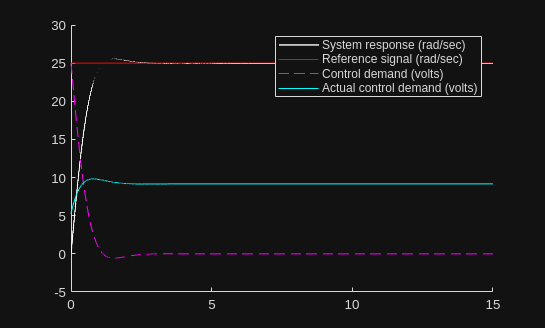

% here we will be simulating with the saturation of +vref and l gain of 1
sim('PID_saturated.slx');
% Reset sim initial conditions
set_param('PID_saturated', 'LoadInitialState', 'off');
set_param('PID_saturated', 'SaveFinalState', 'off');
% Plotting the results from the saturated PID control
figure(4); hold on;
hkp_ref3 = plot([0 tsim(end)], [ref_speed ref_speed], 'r');
hKp_saturated = plot(tsim, theta_dot, 'w', 'LineWidth', 1.0);
hv_demand_sat = plot(tsim, control_demand, 'm--', 'LineWidth', 0.5);
hv_demand_actual = plot(tsim, control, 'c', 'LineWidth', 0.5);

legend([hKp_saturated, hkp_ref3, hv_demand_sat, hv_demand_actual], ...
    {'System response (rad/sec)', ...
     'Reference signal (rad/sec)', ...
     'Control demand (volts)', ...
     'Actual control demand (volts)'}, ...
    'Location', 'northeast');

## Now discretizing the model

TS = 0.3  %                                                                                                                                                                                                                                                                                                                                                                                                             SAQqqqqqqqqqqqqqqQQQqqqqqQQqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqqstep timer